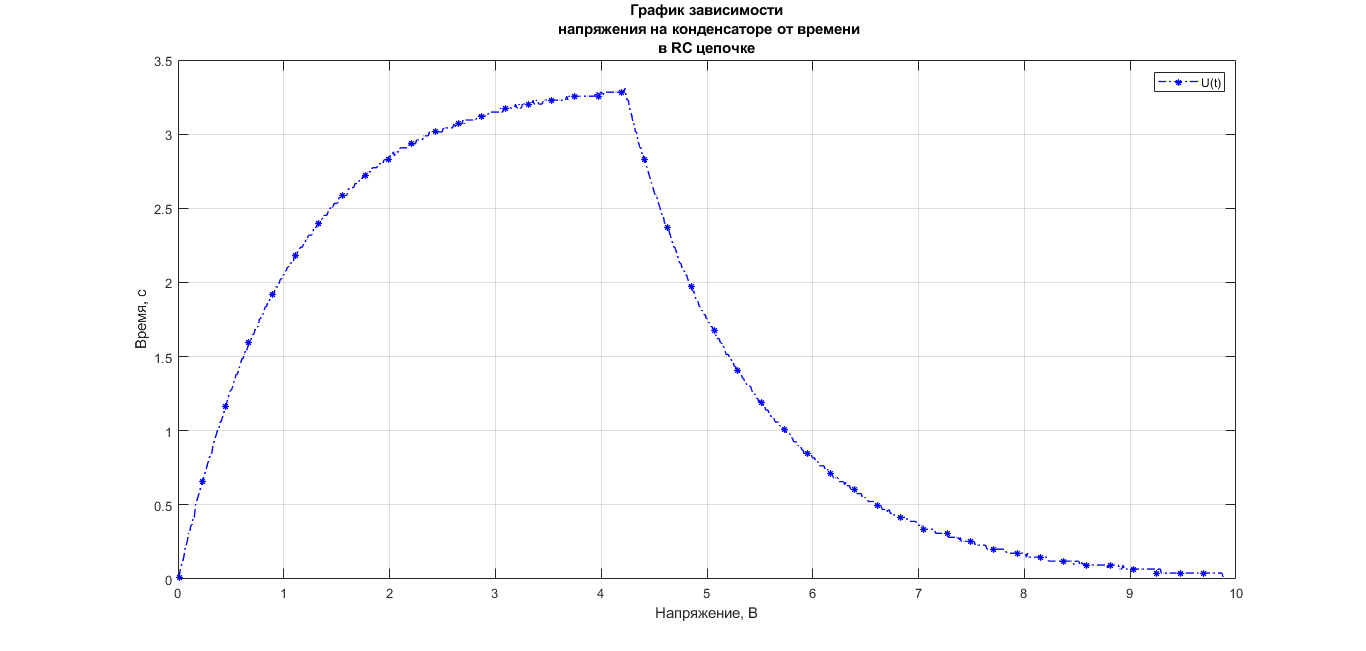

close all;
clear variables;

data = importdata("data.txt");
step = importdata("settings.txt");
V = data * step(1);
T = (1:length(data)) * step(2);


f = figure("Name","Федурина Алена, Б03-008","NumberTitle","off");
plot(T,V,"b-.*","LineWidth",1,"MarkerIndices",1:20:length(V), "MarkerSize",5);
grid on;
xlabel("Напряжение, В");
ylabel("Время, с");
title({'График зависимости',' напряжения на конденсаторе от времени','в RC цепочке'})
legend("U(t)")
set(gcf, 'Visible', 'on');

saveas(f, "capacitor.svg")
saveas(f, "capacitor.png")